## Example of Empirical Orthogonal Function analysis

Load a data set of monthly sea surface temperatures (file cac.mat) for the Pacific Ocean the NOAA Climate Analysis Center. These data were originally acquired from the Live Access Server at the National Virtual Ocean Data System (NVODS) http://ferret.pmel.noaa.gov/NVODS/servlets/dataset which is no longer functioning

A  similar data set can be obtained at [http://coastwatch.pfeg.noaa.gov/erddap/griddap/erdHadISST.html](http://coastwatch.pfeg.noaa.gov/erddap/griddap/erdHadISST.html)

By entering constraints on longitude and latitude, ERDDAP can be used to get a quick look plot east Pacific SST in January 1980: [https://coastwatch.pfeg.noaa.gov/erddap/griddap/erdHadISST.graph?sst%5B(1980-01-16T12:00:00Z)%5D%5B(25.5):(-24.5)%5D%5B(-179.5):(-79.5)%5D&.draw=surface&.vars=longitude%7Clatitude%7Csst&.colorBar=%7C%7C%7C15%7C30%7C&.bgColor=0xffccccff](https://coastwatch.pfeg.noaa.gov/erddap/griddap/erdHadISST.graph?sst%5B(1980-01-16T12:00:00Z)%5D%5B(25.5):(-24.5)%5D%5B(-179.5):(-79.5)%5D&.draw=surface&.vars=longitude%7Clatitude%7Csst&.colorBar=%7C%7C%7C15%7C30%7C&.bgColor=0xffccccff) 

From that plot you can go to the [Data Access Form](https://coastwatch.pfeg.noaa.gov/erddap/griddap/erdHadISST.html?sst%5B(1980-01-16T12:00:00Z)%5D%5B(25.5):(-24.5)%5D%5B(-179.5):(-79.5)%5D&.draw=surface&.vars=longitude%7Clatitude%7Csst&.colorBar=%7C%7C%7C15%7C30%7C&.bgColor=0xffccccff) to perform the actual data download. 

John Wilkin - Originally a simple script April, 2004 - converted to live script 2021

#### Load the data subset saved as a Matlab structure in cac.mat

load cac
load soi
coast = load('coastdat'); % Simple coastline database for plotting

% Break out variables in structure to individual variables in the workspace
lat = cac.lat;
lon = cac.lon;
sst = cac.sst;
land = cac.land;
year = cac.year;

% Get the lengths of the 3 dimensions of SST
[nlats,nlons,ntimes] = size(sst);

% The Climate Analysis Center (CAC) data include both land and sea
% temperatures. We don't expect temperature variability to necessarily be
% strongly correlated to the adjacent sea temperature, so we should exclude
% land values from the data set. This can be done by setting all land
% values to zero, or explicitly excluding them from the data set.

#### Plot the sequence of SST data

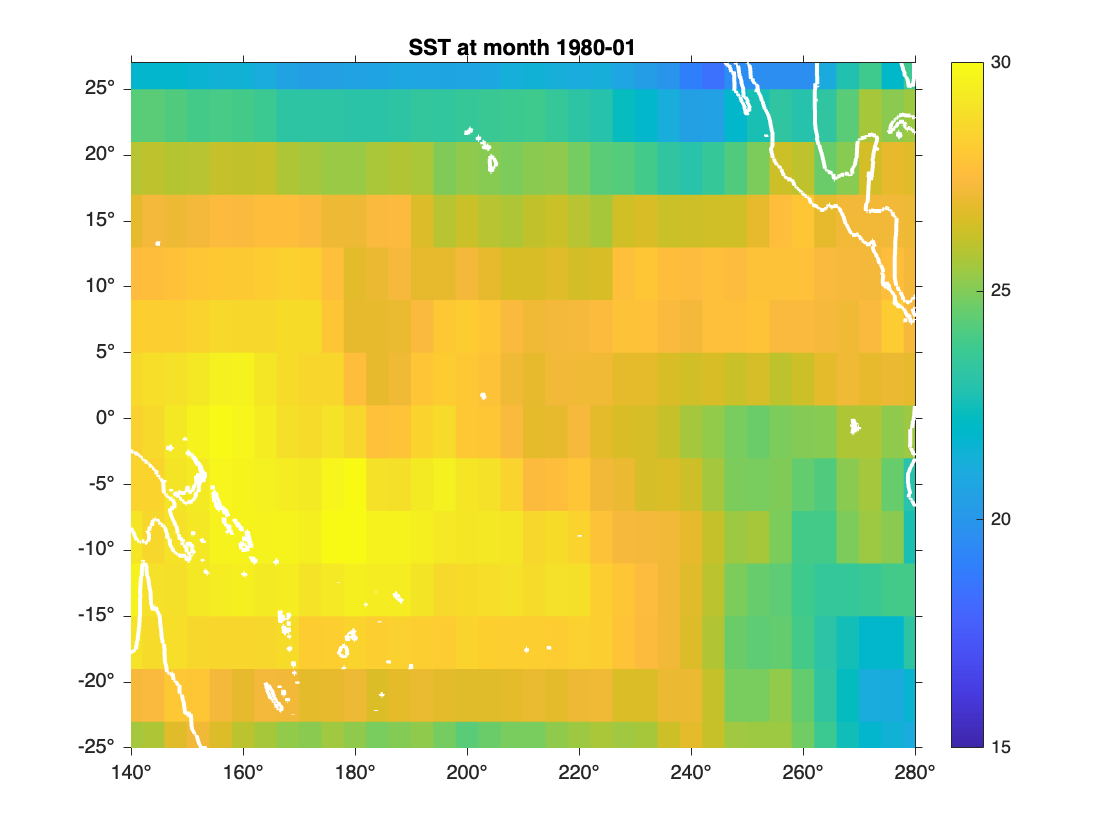

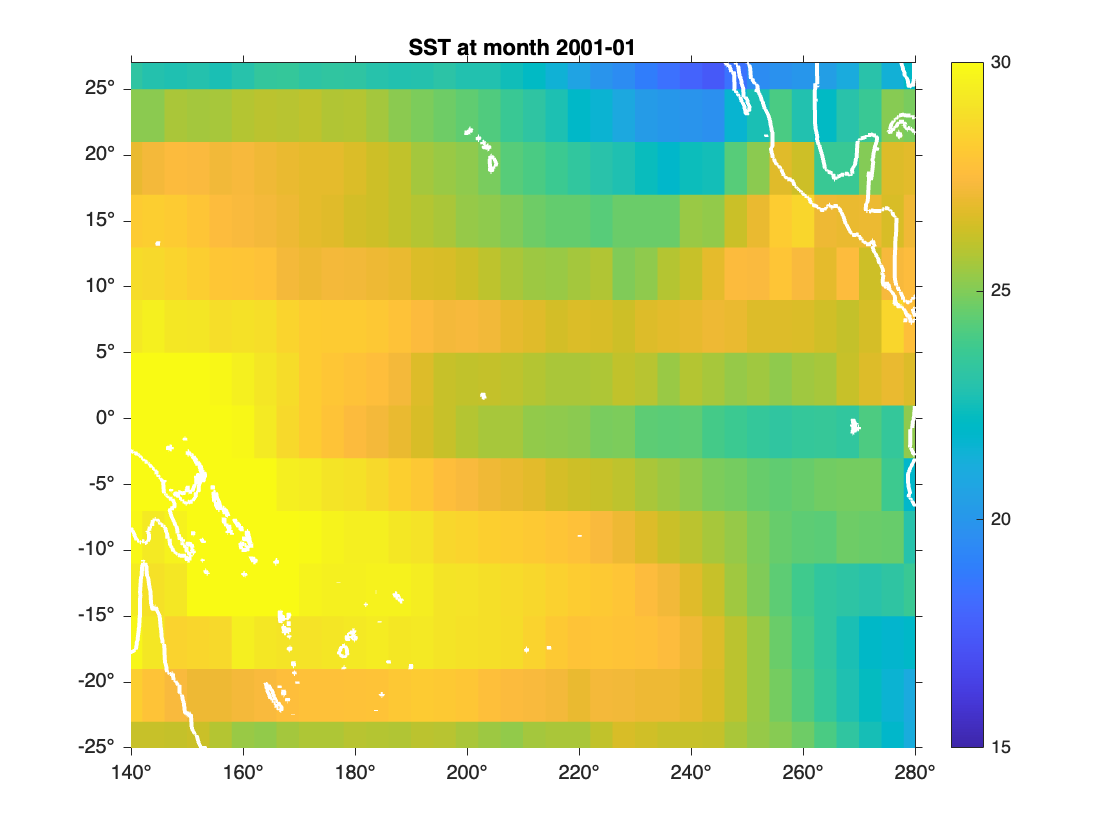

figure
cax = [15 30];
cmocean('thermal')
first = true;
for i=1:12:ntimes
  % step through several images to see roughly what the data look like
  pcolorjw(lon,lat,sst(:,:,i));
  xtickformat('degrees');
  ytickformat('degrees');
  set(gca,'tickdir','out')
  caxis(cax)
  colorbar
  mm = round(rem(year(i),1)*12+0.5);
  MM = sprintf('%02d',mm);
  title(['SST at month ' int2str(floor(year(i))) '-' MM] )
  hold on;
  han = plot(coast.coastdata_x,coast.coastdata_y,'-');
  set(han,'Color','w','LineWidth',2)
  hold off
  drawnow
end

#### Plot a longitude-time Hovmuller diagram

figure
latindex = 7;
pcolorjw(lon,year,sst(latindex,:,:))

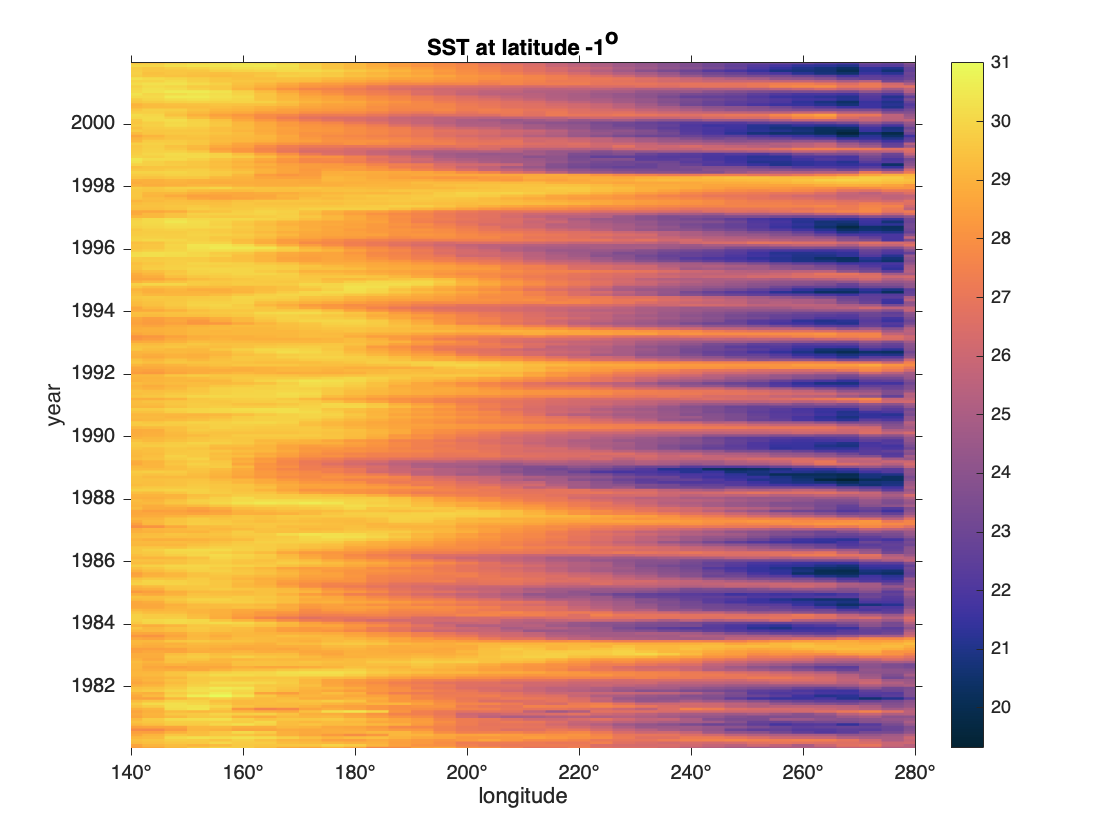

cmocean('thermal')
colorbar
xtickformat('degrees');
set(gca,'tickdir','out')
titlestr = ['SST at latitude ' num2str(lat(latindex)) '^o'];
title(titlestr)
xlabel('longitude')
ylabel('year')

#### Reshape to form a 2-dimensional data matrix

% row index corresponds to position
% column index corresponds to time
D = reshape(sst,[nlats*nlons ntimes]);
size(D)

ans =    504   264


#### Possibly remove deterministic signals such as mean annual cycle

rmann = false;
if rmann

  % Remove annual harmonic
  Eann = [ones(size(year(:))) cos(2*pi*year(:)) sin(2*pi*year(:))];
  coeff = Eann\D';
  Dann = (Eann*coeff)';
  D = D-Dann;
  sstmean = Dann;
  sstanom = D;
  sstmean = reshape(sstmean,[nlats nlons ntimes]);
  sstanom = reshape(sstanom,[nlats nlons ntimes]);
  
  % replot Hovmuller
  pcolorjw(lon,year,sstanom(latindex,:,:))
  cmocean('curl','zero')
  set(gca,'tickdir','out')
  title({titlestr,'Re-plotted Hovmuller with annual cycle removed'});
  colorbar
  
else
  % Must at least remove time mean of each time series (each
  % row of D). Some texts refer to this as "time centering"
  % the data
  Dmean = repmat(mean(D,2),[1 ntimes]);
  D = D-Dmean;
  sstmean = Dmean;
  sstanom = D;
  sstmean = reshape(sstmean,[nlats nlons ntimes]);
  sstanom = reshape(sstanom,[nlats nlons ntimes]);
end

#### Compute EOFs using Singular Value Decomposition

% Compute the SVD of the data matrix
timer = cputime;
[U,S,V] = svd(D,0);
svd_time = cputime-timer;
disp(['SVD took ' num2str(svd_time) ' cpu seconds'])

SVD took 0.24 cpu seconds



% Left singular vectors are the columns of U.
% These are the EOF loadings or mode patterns

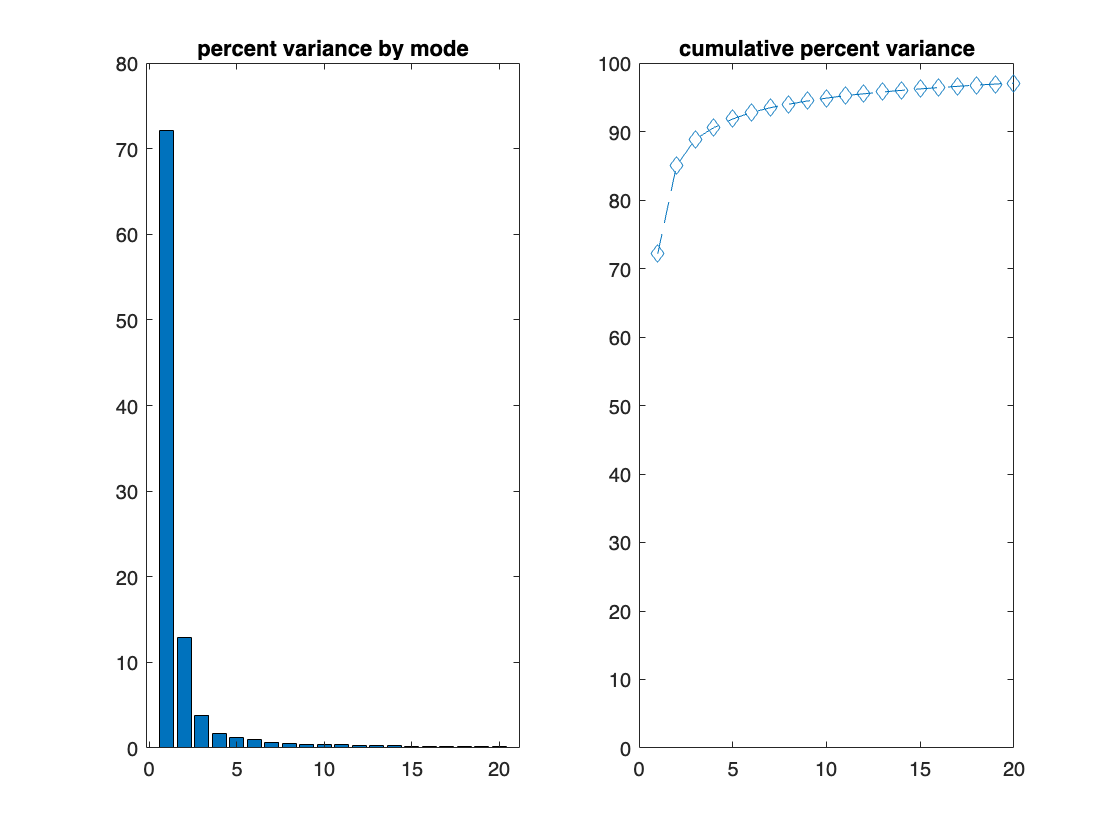

% Singular values are the diagonal elements of S and have the units of the
% data (U and V are normalized). Take S.^2 to get variance of each EOF
L = S*S';
percent_variance = 100*diag(L)/trace(L);

figure
K = 20;
subplot(121)
bar(percent_variance(1:K))
title('percent variance by mode')
subplot(122)
plot(1:K,cumsum(percent_variance(1:K)),'d--')
ylim([0 100])
title('cumulative percent variance')

#### Right singular vectors are the columns of V with information about the mode time series

% Construct the amplitude time series from the product S*V' then each row of A
% is the amplitude times series corresponding to each column of U

A = S*V';

#### Plot the EOF loadings / mode structures

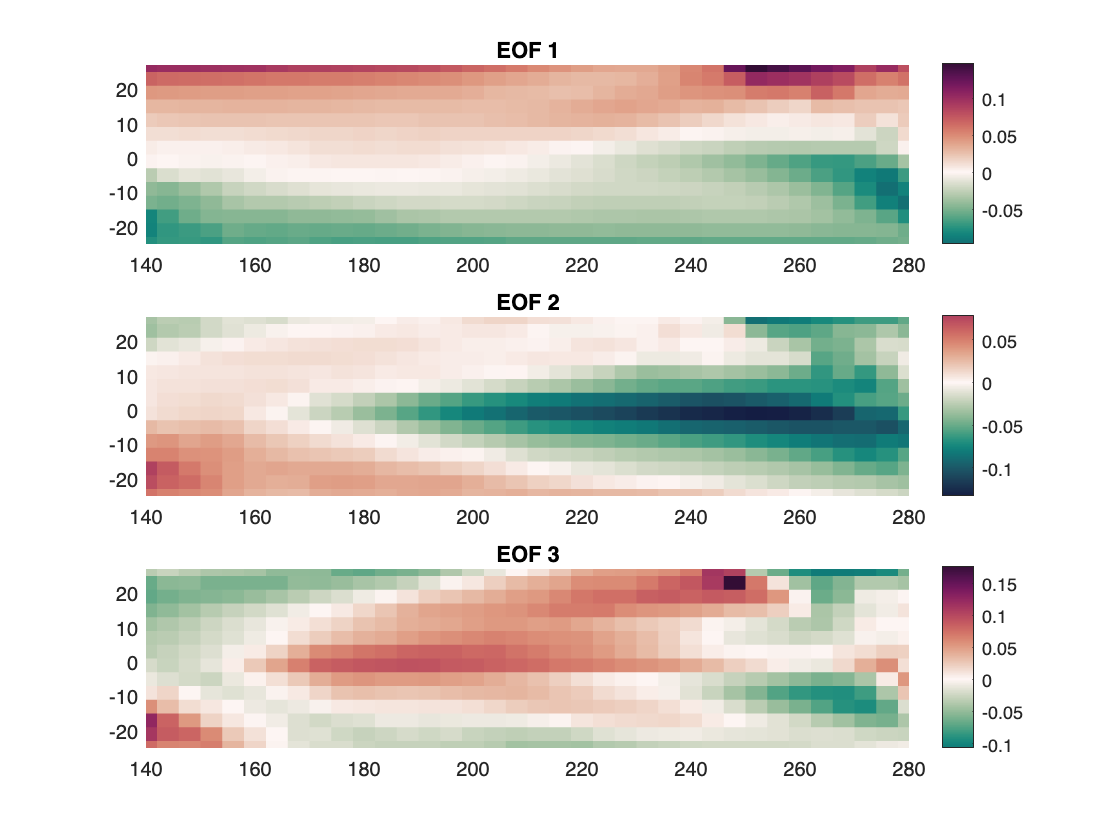

figure
for k=1:3
  subplot(3,1,k)
  pcolorjw(lon,lat,reshape(U(:,k),[nlats nlons]))
  colormap(gca,cmap_cmocean('curl','zero'))
  colorbar
  title(['EOF ' int2str(k)])
end

#### Plot the EOF amplitude time series

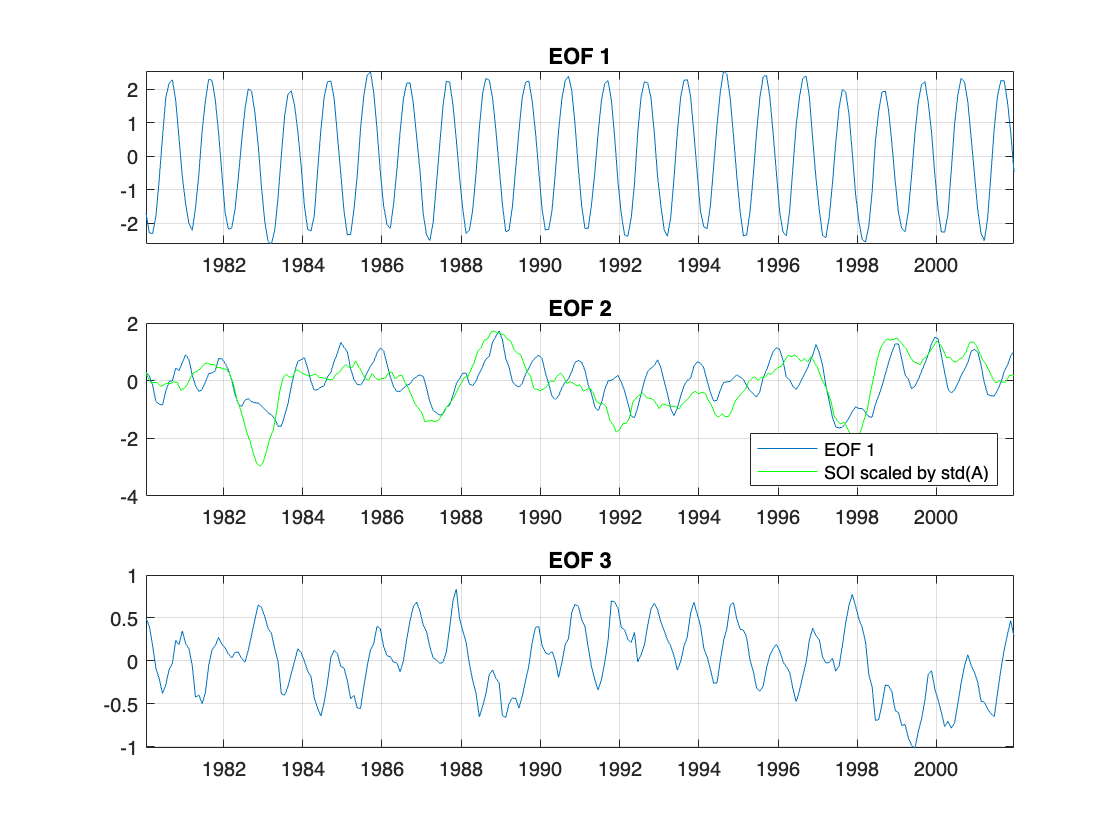

figure
N = size(D,2);
for k=1:3
  subplot(3,1,k)
  plot(year,A(k,:)/sqrt(N))
  set(gca,'xlim',[min(year) max(year)])
  grid on
  title(['EOF ' int2str(k)])
  if rmann
    if k==1
      hold on
      plot(soit/365.25,-std(A(k,:)/sqrt(N))*smooth(soi,7,'moving'),'g')
      hold off
      legend('EOF 1','SOI scaled by std(A)','Location','SouthEast')
    end
  else
    if k==2
      hold on
      plot(soit/365.25,std(A(k,:)/sqrt(N))*smooth(soi,7,'moving'),'g')
      hold off
      legend('EOF 1','SOI scaled by std(A)','Location','SouthEast')
    end
  end
end

#### Compute EOFs from eigenvalues of the covariance matrix

C = D*D';
timer = cputime;
[E,Le] = eig(C);
disp(['EIG took ' num2str(cputime-timer) ' cpu seconds'])

EIG took 0.24 cpu seconds


disp(['SVD took ' num2str(svd_time) ' cpu seconds'])

SVD took 0.24 cpu seconds



% eig output is in order of ascending eigenvalue, so flip order
diagLe = flipud(diag(Le));
100*diagLe(1:K)/trace(Le)

ans =    72.1478
   12.8626
    3.8514
    1.7274
    1.2454
    0.9392
    0.6983
    0.5249
    0.4653
    0.4120


#### Plot EOF 1

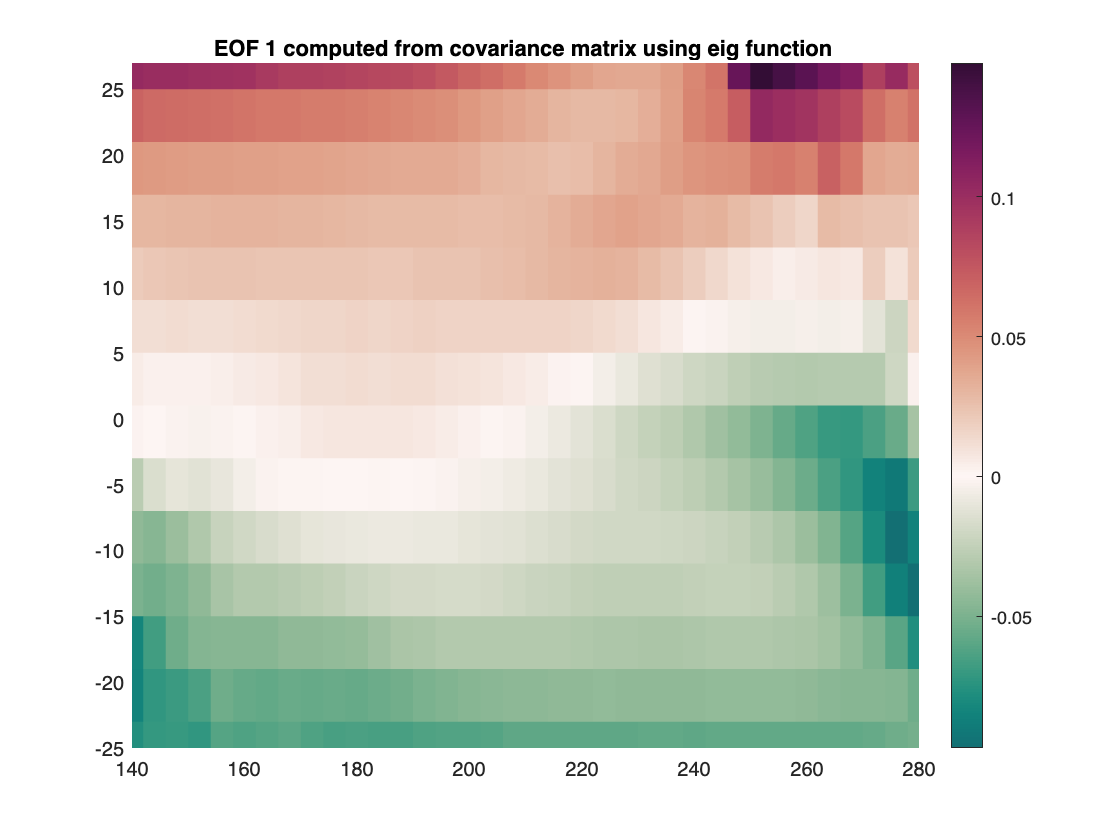

EOF1 = reshape(E(:,end),[nlats nlons]);
% take the "end" because that's the most significant mode from eig
figure
pcolorjw(lon,lat,EOF1)
title('EOF 1 computed from covariance matrix using eig function ')
colorbar
cmocean('curl','zero')

#### Check sum of hierarchy of EOFs against original data

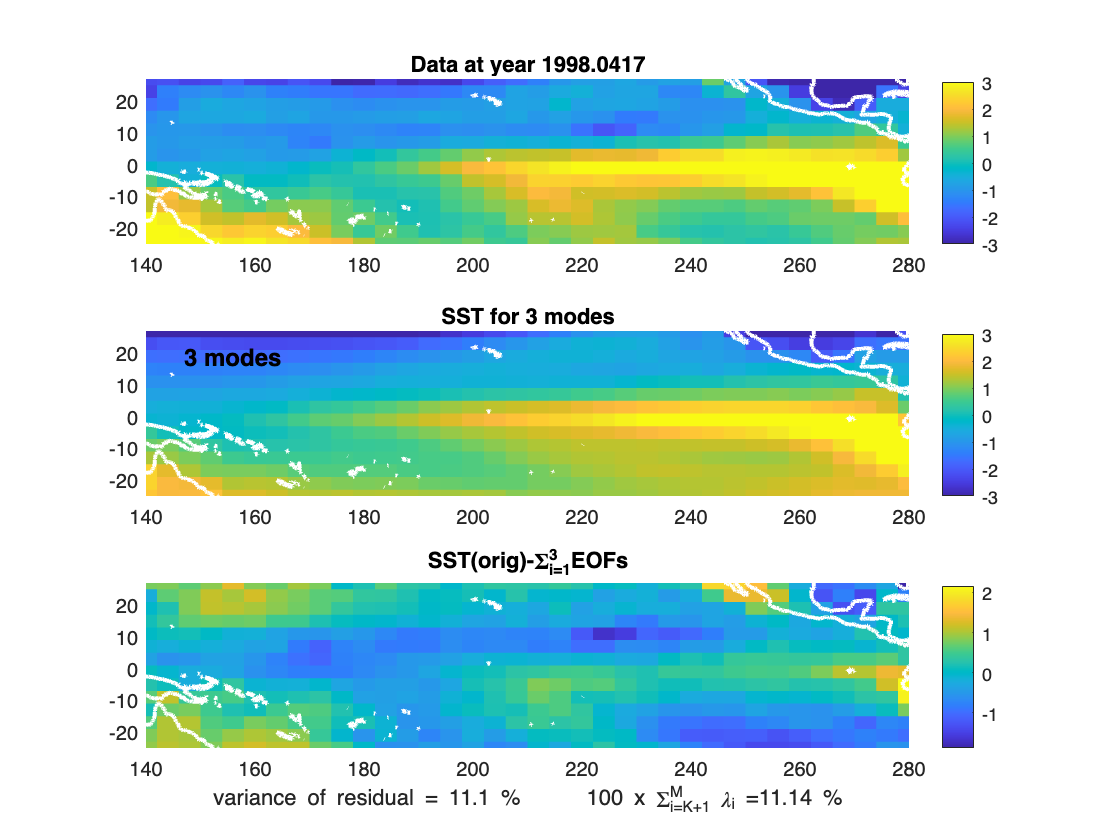

% show = 'full';
show = 'anom';
figure
for K = 1:3
  sst0 = U(:,1:K)*A(1:K,:);
  sst0 = reshape(sst0,[nlats nlons ntimes]);
  switch show
    case 'full'
      sst0 = sst0 + sstmean;
      sstdata = sst;
      cax = [15 30];
    case 'anom'
      sstdata = sstanom;
      cax = 3*[-1 1];
  end
  
  cmocean('thermal')
  tindex = 217; % time index during strong El Niño
  subplot(311)
  pcolorjw(lon,lat,sstdata(:,:,tindex))
  caxis(cax)
  colorbar
  title(['Data at year ' num2str(year(tindex))])
  hold on; han = plot(coast.coastdata_x,coast.coastdata_y,'k-'); hold off
  set(han,'Color','w','LineWidth',2)
  
  subplot(312)
  pcolorjw(lon,lat,sst0(:,:,tindex))
  caxis(cax)
  colorbar
  plural = ' mode'; if K>1, plural =' modes'; end
  title(['SST for ' int2str(K) plural])
  text(147,19,[int2str(K) plural],'fontsize',12,'fontweight','bold')
  hold on; han = plot(coast.coastdata_x,coast.coastdata_y,'k-'); hold off
  set(han,'Color','w','LineWidth',2)
  
  subplot(313)
  pcolorjw(lon,lat,sstdata(:,:,tindex)-sst0(:,:,tindex))
  colorbar
  title(['SST(orig)-\Sigma_{i=1}^' int2str(K) 'EOFs'])
  hold on; han = plot(coast.coastdata_x,coast.coastdata_y,'k-'); hold off
  set(han,'Color','w','LineWidth',2)
  
  xlab1 = ...
    ['variance of residual = ' ...
    num2str(100*(var(sstdata(:)-sst0(:)))/var(sstanom(:)),3) ' %'];
  xlab2 = ...
    ['100 x \Sigma_{i=K+1}^M \lambda_i =' ...
    num2str(sum(percent_variance((K+1):end)),4) ' %'];
  xlabel([xlab1 '      ' xlab2])
  
end